
f = @(x) x.^3 - 4*x.^2 + 6*x - exp(0.1*x);

% Interval and number of points
a = 1;
b = 4;
n = 20;               
h = (b - a) / n;      

% Generate points
x = a:h:b;
fx = f(x);           

[~, idx] = min(fx);

if idx == 1
    disp('Minimum at the left endpoint; cannot bracket');
elseif idx == length(x)
    disp('Minimum at the right endpoint; cannot bracket');
else
    x1 = x(idx - 1);
    x2 = x(idx);
    x3 = x(idx + 1);
    fprintf('Bracketed minimum in interval: (%.2f, %.2f, %.2f)\n', x1, x2, x3);
end

Minimum at the left endpoint; cannot bracket


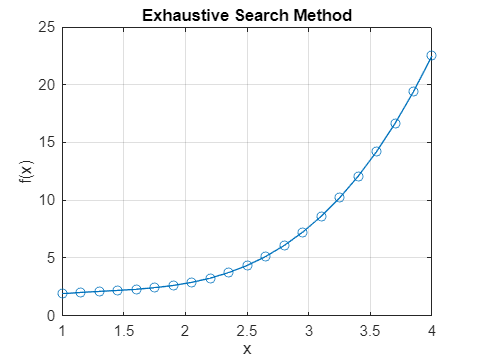



plot(x, fx, '-o');
xlabel('x');
ylabel('f(x)');
title('Exhaustive Search Method');
grid on;

## question 2


f = @(x) sqrt(x.^2 + 1) - 2*x;

a = -2.5;
b = 1;
n = 15;
h = (b - a) / n;
x = a:h:b;
fx = f(x);
for i = 2:length(x)-1
    if fx(i) < fx(i-1) && fx(i) < fx(i+1)
        fprintf('Minimum lies between [%.4f, %.4f]\n', x(i-1), x(i+1));
        break;
    end
end


## question 3


f = @(x) sqrt(x.^2 + 1) - 2*x;

a = -2.5;
b = 1;
n = 15;                
h = (b - a) / n;      


x = a:h:b;             
fx = f(x);   

% Find index of minimum value
[~, idx] = min(fx);

% Bracket the minimum
if idx == 1 || idx == length(x)
    disp('Minimum occurs at the boundary; cannot bracket minimum.');
else
    x1 = x(idx - 1);
    x2 = x(idx);
    x3 = x(idx + 1);
    fprintf('Bracketed minimum is in the interval: (%.2f, %.2f, %.2f)\n', x1, x2, x3);
end

Minimum occurs at the boundary; cannot bracket minimum.


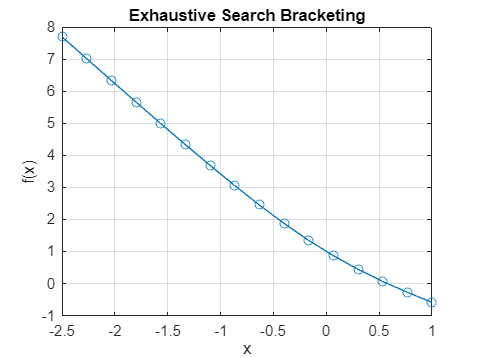

plot(x, fx, '-o');
xlabel('x'); ylabel('f(x)');
title('Exhaustive Search Bracketing');
grid on;

## question 4

% Define the function
f = @(x) (x.^2).*log(x + 1) - 1./(x + 1);

% Interval and division setup
a = 0.5;
b = 2.5;
n = 10;                  % Number of intervals
h = (b - a) / n;         % Step size

% Generate x points
x = a:h:b;               % 11 points from 0.5 to 2.5
fx = f(x);               % Evaluate f(x) at all points

% Find index of minimum value
[~, idx] = min(fx);

% Bracket the minimum
if idx == 1 || idx == length(x)
    disp('Minimum occurs at boundary; cannot bracket.');
else
    x1 = x(idx - 1);
    x2 = x(idx);
    x3 = x(idx + 1);
    fprintf('Bracketed minimum is in interval: (%.2f, %.2f, %.2f)\n', x1, x2, x3);
end

Minimum occurs at boundary; cannot bracket.


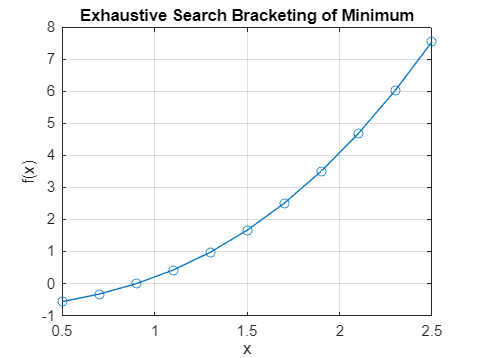


% Optional: Plot the function
plot(x, fx, '-o');
xlabel('x'); ylabel('f(x)');
title('Exhaustive Search Bracketing of Minimum');
grid on;

## question 5

% Define the function
f = @(x) (1 - x).^4 - (2*x + 10).^2;

% Initialize values
x0 = 0.5;             % Initial guess
delta = 0.6;          % Increment parameter
k = 0;

% Evaluate f at x0, x0 + delta, x0 - delta
f0 = f(x0);
f1 = f(x0 + delta);
f_1 = f(x0 - delta);

% Determine direction
if f_1 >= f0 && f1 >= f0
    fprintf('Minimum lies in [%f, %f]\n', x0 - delta, x0 + delta);
    return;
elseif f_1 <= f0 && f0 <= f1
    delta = -delta;  % move left
elseif f_1 >= f0 && f0 >= f1
    % direction is fine (right)
else
    error('Function not unimodal in neighborhood.');
end

% Start iterating in bounding phase
x_prev = x0;
x_curr = x0 + delta;
k = 1;

while true
    x_next = x_curr + (2^k)*delta;
    f_curr = f(x_curr);
    f_next = f(x_next);
    
    if f_next > f_curr
        % Found bracket
        if delta > 0
            a = x_prev;
            b = x_next;
        else
            a = x_next;
            b = x_prev;
        end
        fprintf('Bracketed minimum lies in [%f, %f]\n', a, b);
        break;
    else
        % Update values for next iteration
        x_prev = x_curr;
        x_curr = x_next;
        k = k + 1;
    end
end

Bracketed minimum lies in [1.100000, 4.700000]


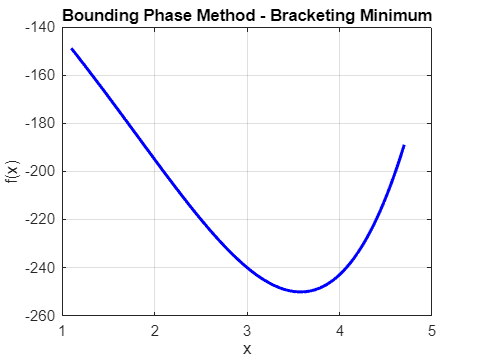


% Optional: Plot function in the bracketing interval
x_vals = linspace(a, b, 100);
plot(x_vals, f(x_vals), 'b-', 'LineWidth', 2);
xlabel('x'); ylabel('f(x)');
title('Bounding Phase Method - Bracketing Minimum');
grid on;

## question 6

% Define the function
f = @(x) exp(((x - 0.2).^2) / 2);

% Initialize
x0 = -10;              % Initial guess
delta = 0.8;           % Increment
k = 0;

% Evaluate at x0, x0+delta, x0-delta
f0 = f(x0);
f1 = f(x0 + delta);
f_1 = f(x0 - delta);

% Determine direction
if f_1 >= f0 && f1 >= f0
    fprintf('Minimum lies in [%f, %f]\n', x0 - delta, x0 + delta);
    return;
elseif f_1 <= f0 && f0 <= f1
    delta = -delta;
elseif f_1 >= f0 && f0 >= f1
    % direction okay
else
    error('Function not unimodal near initial guess.');
end

% Begin bounding phase
x_prev = x0;
x_curr = x0 + delta;
k = 1;

while true
    x_next = x_curr + 2^k * delta;
    f_curr = f(x_curr);
    f_next = f(x_next);

    if f_next > f_curr
        % Bracket found
        if delta > 0
            a = x_prev;
            b = x_next;
        else
            a = x_next;
            b = x_prev;
        end
        fprintf('Bracketed minimum lies in [%f, %f]\n', a, b);
        break;
    else
        % Update values
        x_prev = x_curr;
        x_curr = x_next;
        k = k + 1;
    end
end

Bracketed minimum lies in [-4.400000, 14.800000]


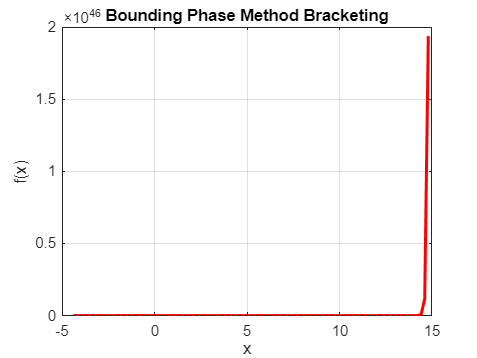


% Optional plot
x_vals = linspace(a, b, 100);
plot(x_vals, f(x_vals), 'r-', 'LineWidth', 2);
xlabel('x'); ylabel('f(x)');
title('Bounding Phase Method Bracketing');
grid on;

## question 7


f = @(x) sqrt(x) - sin(x.^2);

a = 0;
b = 2;
n = 15;
h = (b - a) / n;

x = a:h:b;
fx = f(x);

[~, idx] = min(fx);

if idx == 1 || idx == length(x)
    disp('Minimum is at boundary; cannot bracket.');
else
    fprintf('Bracketed minimum in interval: [%.4f, %.4f, %.4f]\n', ...
        x(idx - 1), x(idx), x(idx + 1));
end

Minimum is at boundary; cannot bracket.


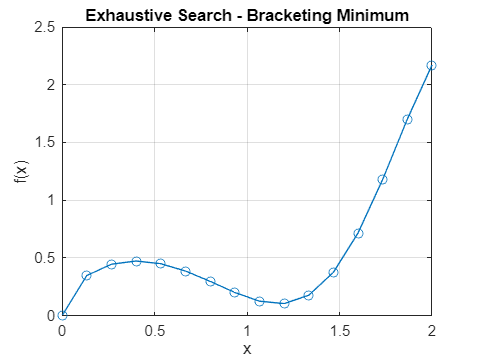

plot(x, fx, '-o'); grid on;
xlabel('x'); ylabel('f(x)');
title('Exhaustive Search - Bracketing Minimum');

## question 8

## a)

% Define the function with safe handling for x = 2
f = @(x) (cos(x).^2 + x) ./ (x - 2);

% Set up the interval
a = -3;
b = 3;
n = 14;                     % Number of intervals
h = (b - a)/n;

% Generate points
x = a:h:b;                  % 15 points
fx = arrayfun(@(xv) f(xv), x);   % Evaluate safely

% Remove the point where x == 2 to avoid NaN
valid_idx = ~isinf(fx) & ~isnan(fx);
x = x(valid_idx);
fx = fx(valid_idx);

% Find index of minimum
[~, idx] = min(fx);

% Bracket the minimum
if idx == 1 || idx == length(x)
    disp('Minimum lies at the boundary, cannot bracket.');
else
    fprintf('Bracketed minimum in: [%.4f, %.4f, %.4f]\n', ...
        x(idx-1), x(idx), x(idx+1));
end

Bracketed minimum in: [1.2857, 1.7143, 2.1429]


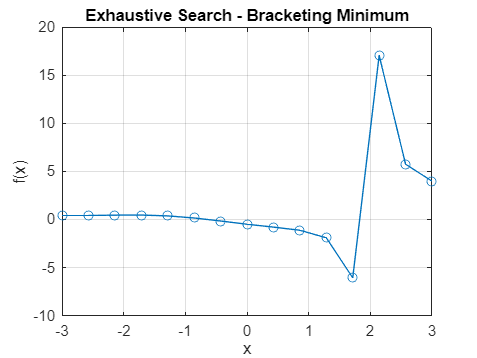


% Plot
plot(x, fx, '-o'); grid on;
xlabel('x'); ylabel('f(x)');
title('Exhaustive Search - Bracketing Minimum');

## b)

% Define the function
f = @(x) (cos(x).^2 + x) ./ (x - 2);

% Initialize
x0 = 0.08;
delta = -0.5;
k = 0;

% Evaluate neighborhood
try
    f0 = f(x0);
    f1 = f(x0 + delta);
    f_1 = f(x0 - delta);
catch
    error('Function evaluation failed due to division by zero');
end

% Determine direction
if f_1 >= f0 && f1 >= f0
    fprintf('Bracketed minimum in: [%.4f, %.4f]\n', x0 - delta, x0 + delta);
    return;
elseif f_1 <= f0 && f0 <= f1
    delta = -delta;
elseif f_1 >= f0 && f0 >= f1
    % direction okay
else
    error('Function not unimodal near starting point.');
end

% Start bounding phase
x_prev = x0;
x_curr = x0 + delta;
k = 1;

while true
    x_next = x_curr + 2^k * delta;

    % Check for domain issue at x = 2
    if abs(x_next - 2) < 1e-6
        disp('x = 2 encountered, aborting to avoid division by zero.');
        break;
    end

    f_curr = f(x_curr);
    f_next = f(x_next);

    if f_next > f_curr
        if delta > 0
            a = x_prev;
            b = x_next;
        else
            a = x_next;
            b = x_prev;
        end
        fprintf('Bracketed minimum in: [%.4f, %.4f]\n', a, b);
        break;
    else
        x_prev = x_curr;
        x_curr = x_next;
        k = k + 1;
    end
end

Bracketed minimum in: [0.5800, 3.5800]


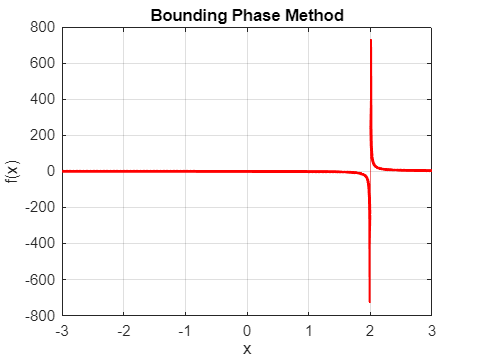


% Optional: Plot
x_vals = linspace(-3, 3, 1000);
fx_vals = f(x_vals);
fx_vals(abs(x_vals - 2) < 1e-4) = NaN; % Remove near x=2

plot(x_vals, fx_vals, 'r', 'LineWidth', 2); grid on;
xlabel('x'); ylabel('f(x)');
title('Bounding Phase Method');